分析代价函数

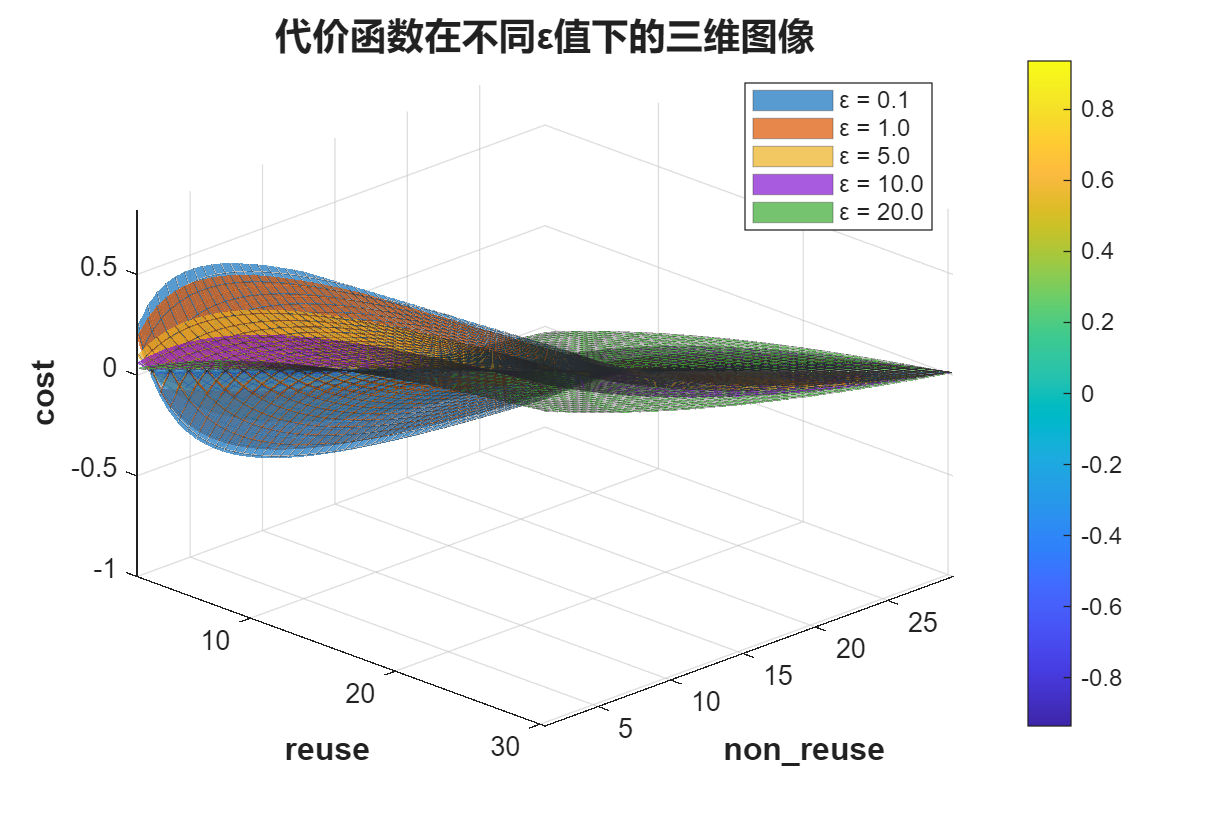

clear; clc; close all;

% 定义变量范围
reuse = linspace(1, 32, 50);
non_reuse = linspace(1, 32, 50);

% 创建网格
[Reuse, Non_reuse] = meshgrid(reuse, non_reuse);

% 定义不同的epsilon值
epsilon_values = [0.1, 1, 5, 10, 20];

% 设置图形
figure('Position', [100, 100, 1200, 800]);
hold on;
grid on;

% 颜色映射（为不同的epsilon值选择不同颜色）
colors = lines(length(epsilon_values));

% 为每个epsilon值绘制曲面
for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    
    % 计算函数值
    Y = (Reuse - Non_reuse) ./ (epsilon + Reuse + Non_reuse);
    
    % 绘制三维曲面
    surf(Reuse, Non_reuse, Y, ...
         'FaceAlpha', 0.7, ...
         'EdgeAlpha', 0.3, ...
         'FaceColor', colors(i,:), ...
         'DisplayName', sprintf('ε = %.1f', epsilon));
end

% 设置图形属性
xlabel('reuse', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('non\_reuse', 'FontSize', 12, 'FontWeight', 'bold');
zlabel('cost', ...
       'FontSize', 12, 'FontWeight', 'bold');
title('代价函数在不同ε值下的三维图像', ...
      'FontSize', 14, 'FontWeight', 'bold');

% 添加图例和颜色条
legend('show', 'Location', 'northeast');
colorbar;

% 设置坐标轴范围
xlim([1, 32]);
ylim([1, 32]);

% 设置视角
view(45, 30);

% 添加网格
grid on;

% 保存图像（可选）
% saveas(gcf, 'function_3d_plot.png');

hold off;

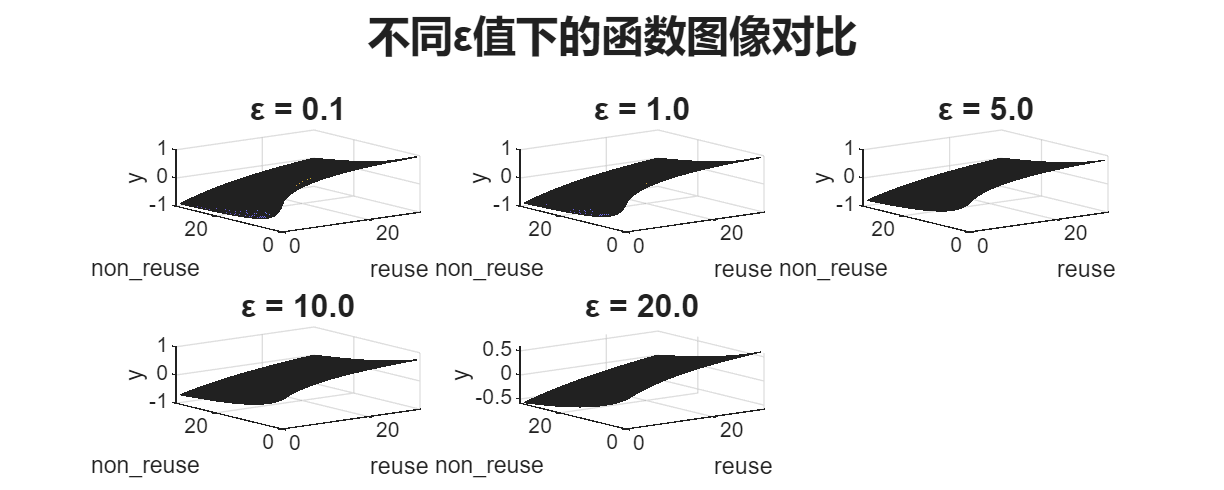


%% 可选：单独绘制每个epsilon的图像进行比较
figure('Position', [100, 100, 1500, 600]);
for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    Y = (Reuse - Non_reuse) ./ (epsilon + Reuse + Non_reuse);
    
    subplot(2, 3, i);
    surf(Reuse, Non_reuse, Y, 'FaceAlpha', 0.8);
    title(sprintf('ε = %.1f', epsilon), 'FontSize', 12, 'FontWeight', 'bold');
    xlabel('reuse');
    ylabel('non\_reuse');
    zlabel('y');
    grid on;
end

% 为子图添加总标题
sgtitle('不同ε值下的函数图像对比', 'FontSize', 16, 'FontWeight', 'bold');

分析代价函数的全微分

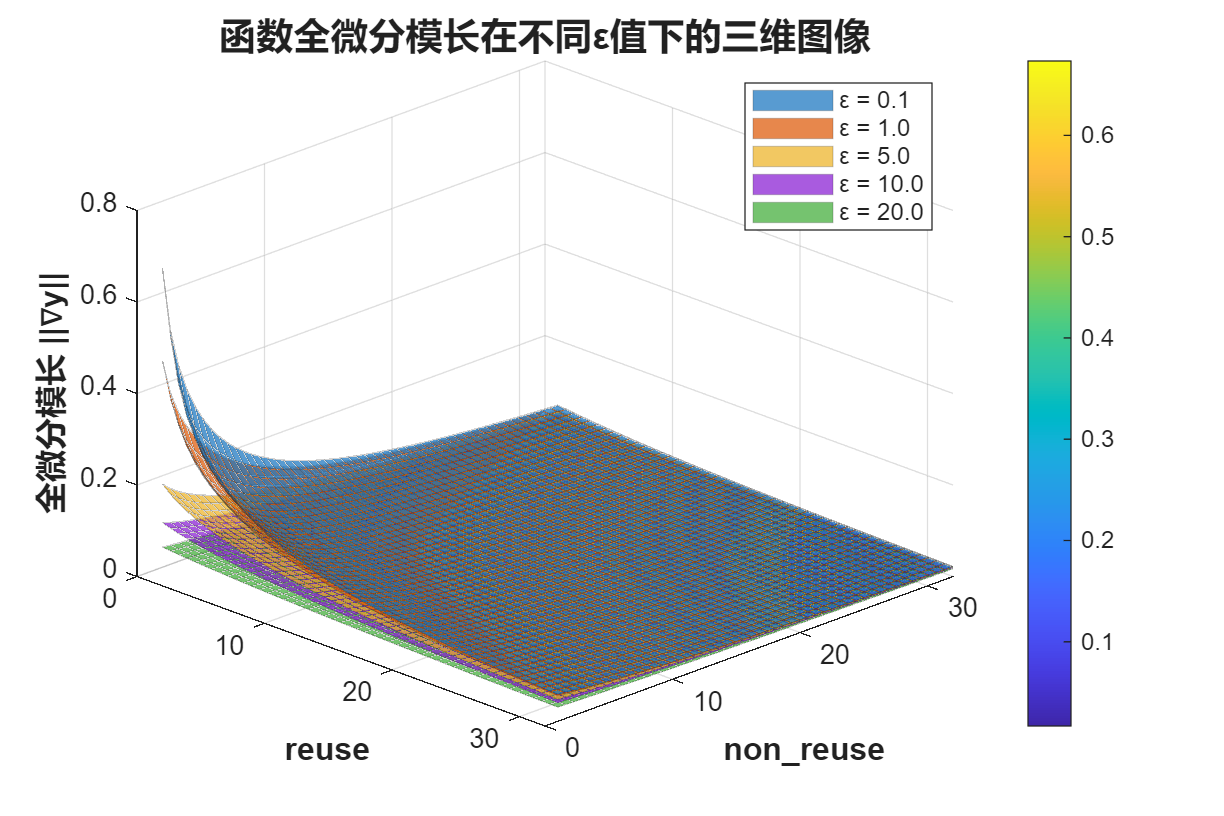

% 清理环境
clear; clc; close all;

% 定义变量范围
reuse = linspace(1, 32, 50);
non_reuse = linspace(1, 32, 50);

% 创建网格
[Reuse, Non_reuse] = meshgrid(reuse, non_reuse);

% 定义不同的epsilon值
epsilon_values = [0.1, 1, 5, 10, 20];

% 计算全微分
% 函数: y = (reuse - non_reuse) / (epsilon + reuse + non_reuse)
% 对reuse的偏导数: dy/d_reuse = (epsilon + 2*non_reuse) / (epsilon + reuse + non_reuse)^2
% 对non_reuse的偏导数: dy/d_non_reuse = -(epsilon + 2*reuse) / (epsilon + reuse + non_reuse)^2
% 全微分模长: ||∇y|| = sqrt((dy/d_reuse)^2 + (dy/d_non_reuse)^2)

%% 绘制全微分模长的三维图像
figure('Position', [100, 100, 1200, 800]);
hold on;
grid on;

% 颜色映射
colors = lines(length(epsilon_values));

for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    
    % 计算偏导数
    dY_dReuse = (epsilon + 2*Non_reuse) ./ (epsilon + Reuse + Non_reuse).^2;
    dY_dNon_reuse = -(epsilon + 2*Reuse) ./ (epsilon + Reuse + Non_reuse).^2;
    
    % 计算全微分模长（梯度向量的长度）
    gradient_magnitude = sqrt(dY_dReuse.^2 + dY_dNon_reuse.^2);
    
    % 绘制三维曲面
    surf(Reuse, Non_reuse, gradient_magnitude, ...
         'FaceAlpha', 0.7, ...
         'EdgeAlpha', 0.2, ...
         'FaceColor', colors(i,:), ...
         'DisplayName', sprintf('ε = %.1f', epsilon));
end

% 设置图形属性
xlabel('reuse', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('non\_reuse', 'FontSize', 12, 'FontWeight', 'bold');
zlabel('全微分模长 ||∇y||', 'FontSize', 12, 'FontWeight', 'bold');
title('函数全微分模长在不同ε值下的三维图像', 'FontSize', 14, 'FontWeight', 'bold');

legend('show', 'Location', 'northeast');
colorbar;
view(45, 30);

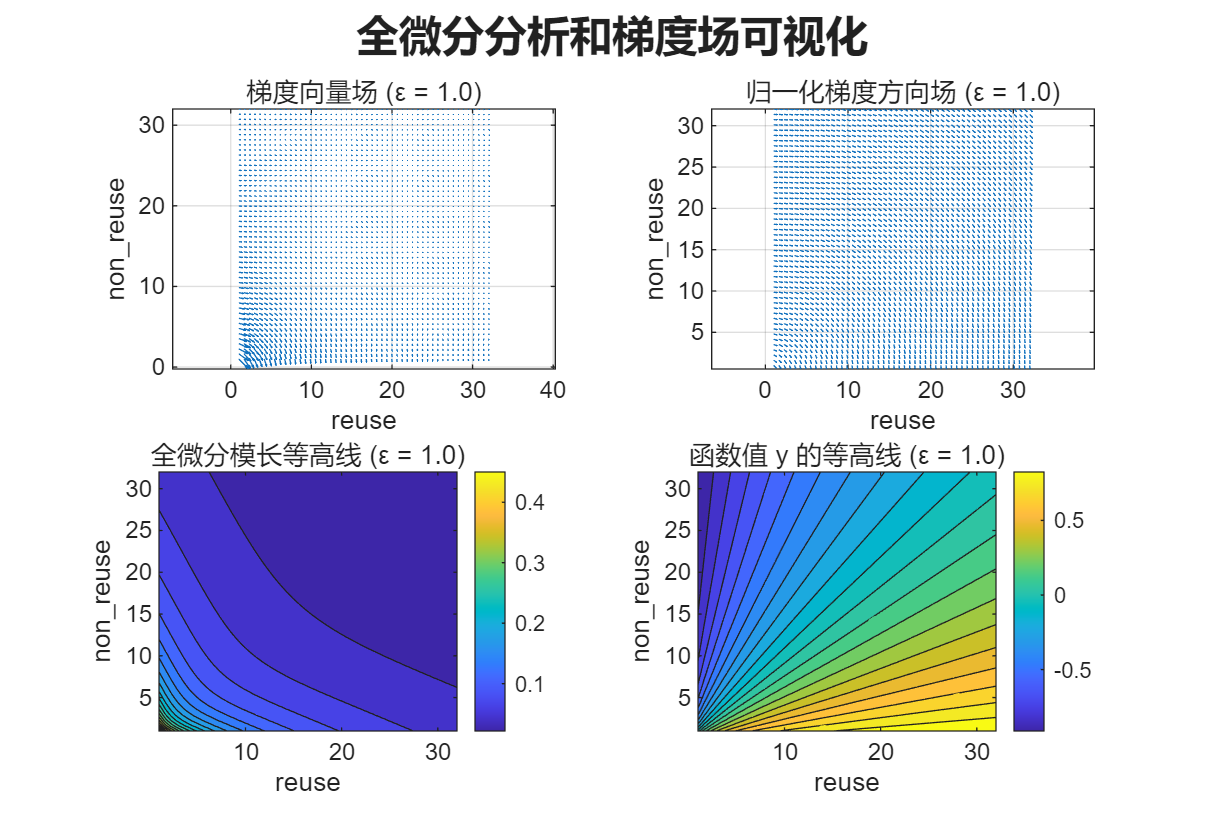


%% 绘制梯度向量场（二维投影）
figure('Position', [100, 100, 1200, 800]);

% 选择其中一个epsilon值进行演示
epsilon = 1;

% 计算偏导数
dY_dReuse = (epsilon + 2*Non_reuse) ./ (epsilon + Reuse + Non_reuse).^2;
dY_dNon_reuse = -(epsilon + 2*Reuse) ./ (epsilon + Reuse + Non_reuse).^2;

% 绘制梯度向量场
subplot(2, 2, 1);
quiver(Reuse, Non_reuse, dY_dReuse, dY_dNon_reuse, 2);
xlabel('reuse');
ylabel('non\_reuse');
title(sprintf('梯度向量场 (ε = %.1f)', epsilon));
axis equal;
grid on;

% 绘制梯度方向场
subplot(2, 2, 2);
% 归一化梯度向量以显示方向
gradient_magnitude = sqrt(dY_dReuse.^2 + dY_dNon_reuse.^2);
dY_dReuse_normalized = dY_dReuse ./ (gradient_magnitude + 1e-10); % 避免除零
dY_dNon_reuse_normalized = dY_dNon_reuse ./ (gradient_magnitude + 1e-10);

quiver(Reuse, Non_reuse, dY_dReuse_normalized, dY_dNon_reuse_normalized, 0.5);
xlabel('reuse');
ylabel('non\_reuse');
title(sprintf('归一化梯度方向场 (ε = %.1f)', epsilon));
axis equal;
grid on;

% 绘制全微分模长的等高线图
subplot(2, 2, 3);
contourf(Reuse, Non_reuse, gradient_magnitude, 20);
xlabel('reuse');
ylabel('non\_reuse');
title(sprintf('全微分模长等高线 (ε = %.1f)', epsilon));
colorbar;

% 绘制函数值等高线
subplot(2, 2, 4);
Y = (Reuse - Non_reuse) ./ (epsilon + Reuse + Non_reuse);
contourf(Reuse, Non_reuse, Y, 20);
xlabel('reuse');
ylabel('non\_reuse');
title(sprintf('函数值 y 的等高线 (ε = %.1f)', epsilon));
colorbar;

sgtitle('全微分分析和梯度场可视化', 'FontSize', 16, 'FontWeight', 'bold');

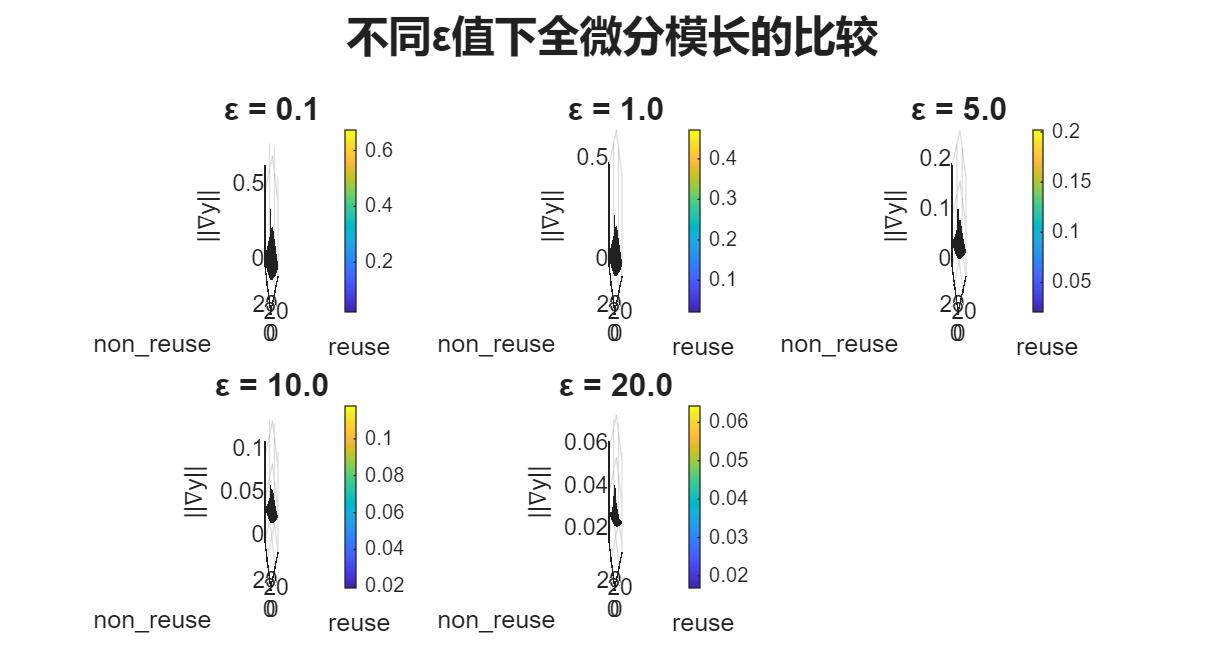


%% 比较不同epsilon下的全微分特性
figure('Position', [100, 100, 1500, 800]);

for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    
    % 计算全微分模长
    dY_dReuse = (epsilon + 2*Non_reuse) ./ (epsilon + Reuse + Non_reuse).^2;
    dY_dNon_reuse = -(epsilon + 2*Reuse) ./ (epsilon + Reuse + Non_reuse).^2;
    gradient_magnitude = sqrt(dY_dReuse.^2 + dY_dNon_reuse.^2);
    
    subplot(2, 3, i);
    surf(Reuse, Non_reuse, gradient_magnitude, 'FaceAlpha', 0.8);
    title(sprintf('ε = %.1f', epsilon), 'FontSize', 12, 'FontWeight', 'bold');
    xlabel('reuse');
    ylabel('non\_reuse');
    zlabel('||∇y||');
    grid on;
    
    % 添加颜色条以便比较量级
    colorbar;
end

sgtitle('不同ε值下全微分模长的比较', 'FontSize', 16, 'FontWeight', 'bold');

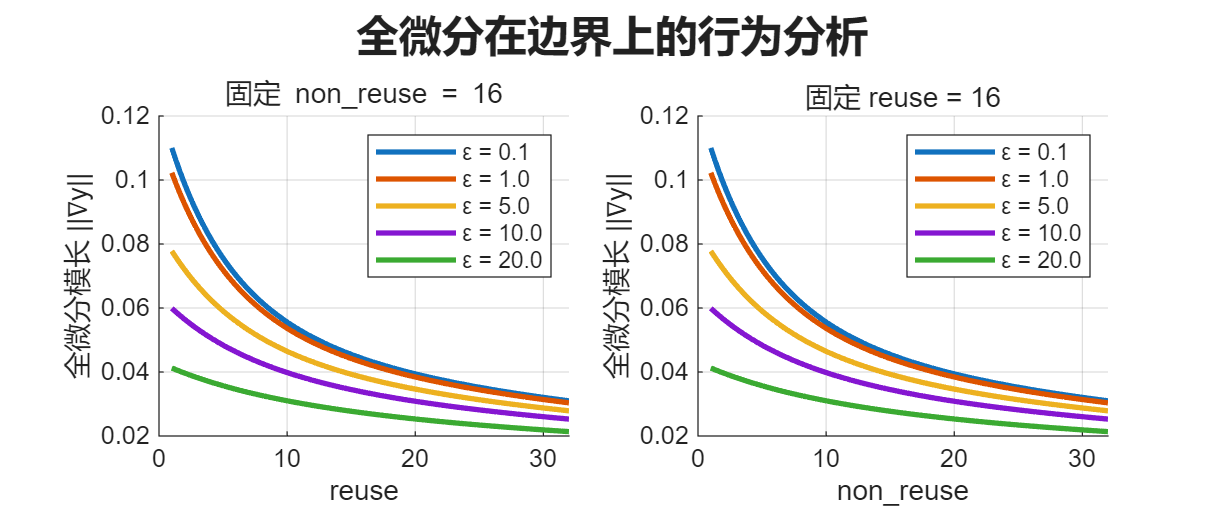


%% 分析全微分在边界的行为
figure('Position', [100, 100, 1200, 500]);

% 固定non_reuse = 16，观察全微分随reuse的变化
fixed_non_reuse = 16;
reuse_line = linspace(1, 32, 100);

subplot(1, 2, 1);
hold on;
for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    
    % 计算偏导数
    dY_dReuse_line = (epsilon + 2*fixed_non_reuse) ./ (epsilon + reuse_line + fixed_non_reuse).^2;
    dY_dNon_reuse_line = -(epsilon + 2*reuse_line) ./ (epsilon + reuse_line + fixed_non_reuse).^2;
    gradient_magnitude_line = sqrt(dY_dReuse_line.^2 + dY_dNon_reuse_line.^2);
    
    plot(reuse_line, gradient_magnitude_line, 'LineWidth', 2, ...
         'DisplayName', sprintf('ε = %.1f', epsilon));
end
xlabel('reuse');
ylabel('全微分模长 ||∇y||');
title(sprintf('固定 non\\_reuse = %d', fixed_non_reuse));
legend('show');
grid on;

% 固定reuse = 16，观察全微分随non_reuse的变化
fixed_reuse = 16;
non_reuse_line = linspace(1, 32, 100);

subplot(1, 2, 2);
hold on;
for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    
    % 计算偏导数
    dY_dReuse_line2 = (epsilon + 2*non_reuse_line) ./ (epsilon + fixed_reuse + non_reuse_line).^2;
    dY_dNon_reuse_line2 = -(epsilon + 2*fixed_reuse) ./ (epsilon + fixed_reuse + non_reuse_line).^2;
    gradient_magnitude_line2 = sqrt(dY_dReuse_line2.^2 + dY_dNon_reuse_line2.^2);
    
    plot(non_reuse_line, gradient_magnitude_line2, 'LineWidth', 2, ...
         'DisplayName', sprintf('ε = %.1f', epsilon));
end
xlabel('non\_reuse');
ylabel('全微分模长 ||∇y||');
title(sprintf('固定 reuse = %d', fixed_reuse));
legend('show');
grid on;

sgtitle('全微分在边界上的行为分析', 'FontSize', 16, 'FontWeight', 'bold');